# SNW_DS_PARAM Dense Solution Analysis

This is the example vignette for function: [**snw_ds_main**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/params/snw_ds_main.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for vfi and gets distribution induced by policy functions and exogenous distributions. Dense Simulation.

## Test SNW_DS_MAIN Defaults Dense

Call the function with testing defaults.

mp_params = snw_mp_param('default_dense');
mp_controls = snw_mp_control('default_test');
mp_controls('bl_print_vfi') = true;
mp_controls('bl_print_ds') = true;
mp_controls('bl_print_vfi_verbose') = false;
mp_controls('bl_print_ds_verbose') = false;
mp_controls('bl_vfi_store_all') = true;
mp_controls('bl_ds_store_all') = true;
[mp_dsvfi_results] = snw_ds_main(mp_params, mp_controls);

SNW_VFI_MAIN: Finished Age Group:83 of 83
SNW_VFI_MAIN: Finished Age Group:82 of 83
SNW_VFI_MAIN: Finished Age Group:81 of 83
SNW_VFI_MAIN: Finished Age Group:80 of 83
SNW_VFI_MAIN: Finished Age Group:79 of 83
SNW_VFI_MAIN: Finished Age Group:78 of 83
SNW_VFI_MAIN: Finished Age Group:77 of 83
SNW_VFI_MAIN: Finished Age Group:76 of 83
SNW_VFI_MAIN: Finished Age Group:75 of 83
SNW_VFI_MAIN: Finished Age Group:74 of 83
SNW_VFI_MAIN: Finished Age Group:73 of 83
SNW_VFI_MAIN: Finished Age Group:72 of 83
SNW_VFI_MAIN: Finished Age Group:71 of 83
SNW_VFI_MAIN: Finished Age Group:70 of 83
SNW_VFI_MAIN: Finished Age Group:69 of 83
SNW_VFI_MAIN: Finished Age Group:68 of 83
SNW_VFI_MAIN: Finished Age Group:67 of 83
SNW_VFI_MAIN: Finished Age Group:66 of 83
SNW_VFI_MAIN: Finished Age Group:65 of 83
SNW_VFI_MAIN: Finished Age Group:64 of 83
SNW_VFI_MAIN: Finished Age Group:63 of 83
SNW_VFI_MAIN: Finished Age Group:62 of 83
SNW_VFI_MAIN: Finished Age Group:61 of 83
SNW_VFI_MAIN: Finished Age Group:6

## Show All Info in mp_dsvfi_results Dense

ff_container_map_display(mp_dsvfi_results);

pos = 14 ; key = mp_cl_mt_xyz_of_s
  Map with properties:

        Count: 8
      KeyType: char
    ValueType: any

pos = 15 ; key = mp_controls
  Map with properties:

        Count: 18
      KeyType: char
    ValueType: any

pos = 16 ; key = mp_params
  Map with properties:

        Count: 29
      KeyType: char
    ValueType: any

----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_dsvfi_results ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                    i    idx    ndim      numel      rowN    colN        sum           mean          std        coe

## Dense Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Probability mass matrixes, Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = 18:100;
agrid = mp_params('agrid')';
eta_grid = mp_params('eta_grid')';
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_params('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'shock', eta_grid});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Probability Mass Along Age Dimensions

Where are the mass at? Analyze mass given state space components.

% Get the Joint distribution over all states
Phi_true = mp_dsvfi_results('Phi_true');
Phi_true = Phi_true/sum(Phi_true(:));
% Define Graph Inputs
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log

#### Exogenous Permanent States Mass: Life Cycle, Edu and Marraige

Tabulate value and policies along savings and shocks:

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,5,4];
% Value Function
tb_prob_aem = ff_summ_nd_array("P(Age, EDU, MARRY))", Phi_true, true, ["sum"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(Age, EDU, MARRY))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    marry    edu    sum_age_18    sum_age_19    sum_age_20    sum_age_21    sum_age_22    sum_age_23    sum_age_24    sum_age_25    sum_age_26    sum_age_27    sum_age_28    sum_age_29    sum_age_30    sum_age_31    sum_age_32    sum_age_33    sum_age_34    sum_age_35    sum_age_36    sum_age_37    sum_age_38    sum_age_39    sum_age_40    sum_age_41    sum_age_42    sum_age_43    sum_age_44    sum_age_45  

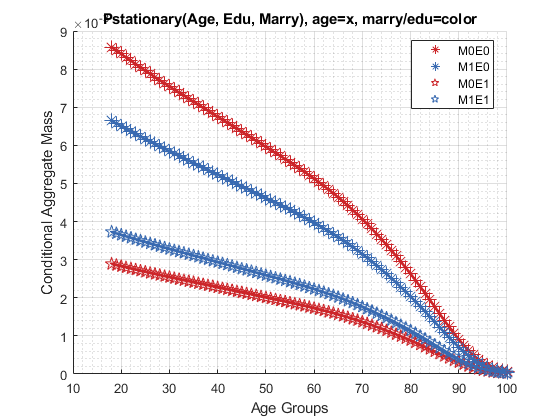

mp_support_graph('cl_st_graph_title') = {'Pstationary(Age, Edu, Marry), age=x, marry/edu=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = ["M0E0", "M1E0", "M0E1", "M1E1"];
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
mp_support_graph('cl_scatter_shapes') = {'*', '*', 'p', 'p' };
mp_support_graph('cl_colors') = {'red', 'blue', 'red', 'blue'};
ff_graph_grid((tb_prob_aem{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

#### Kids and Marry By Age Mass

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_prob_amarrykids = ff_summ_nd_array("P(Age, Kids, Marry))", Phi_true, true, ["sum"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(Age, Kids, Marry))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    sum_age_18    sum_age_19    sum_age_20    sum_age_21    sum_age_22    sum_age_23    sum_age_24    sum_age_25    sum_age_26    sum_age_27    sum_age_28    sum_age_29    sum_age_30    sum_age_31    sum_age_32    sum_age_33    sum_age_34    sum_age_35    sum_age_36    sum_age_37    sum_age_38    sum_age_39    sum_age_40    sum_age_41    sum_age_42    sum_age_43    sum_age_44    sum_age_45

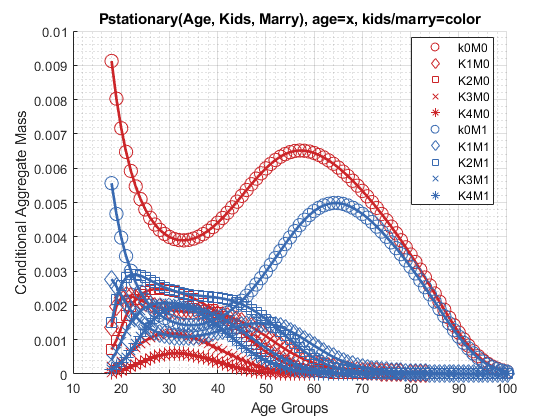

mp_support_graph('cl_st_graph_title') = {'Pstationary(Age, Kids, Marry), age=x, kids/marry=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = [...
    "k0M0", "K1M0", "K2M0", "K3M0", "K4M0", ...
    "k0M1", "K1M1", "K2M1", "K3M1", "K4M1"];
mp_support_graph('cl_scatter_shapes') = {...
    'o', 'd' ,'s', 'x', '*', ...
    'o', 'd', 's', 'x', '*'};
mp_support_graph('cl_colors') = {...
    'red', 'red', 'red', 'red', 'red'...
    'blue', 'blue', 'blue', 'blue', 'blue'};
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
ff_graph_grid((tb_prob_amarrykids{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Probability Mass Asset and Shock Dimensions

Where are the mass at?

% Get the Joint distribution over all states
Phi_true = mp_dsvfi_results('Phi_true');
Phi_true = Phi_true/sum(Phi_true(:));
% Define Graph Inputs
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log

#### Asset and Shock Mass

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_prob_az = ff_summ_nd_array("P(A,Z))", Phi_true, true, ["sum"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings     sum_shock__1_9069    sum_shock__1_4302    sum_shock__0_95346    sum_shock__0_47673    sum_shock_0    sum_shock_0_47673    sum_shock_0_95346    sum_shock_1_4302    sum_shock_1_9069
    _____    _________    _________________    _________________    __________________    __________________    ___________    _________________    _________________    ________________    ________________

      1              0        0.0028759             0.018948              0.049434               0.06777          0.043917          0.014897            0.0033533          

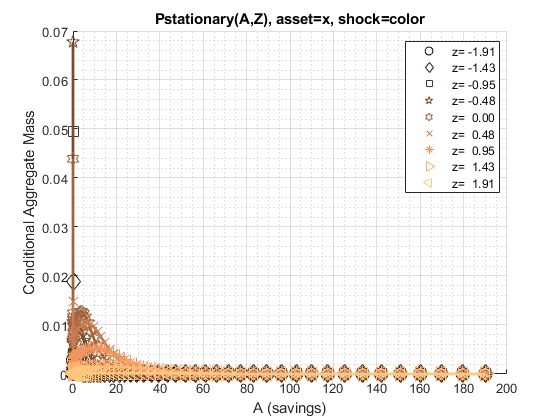

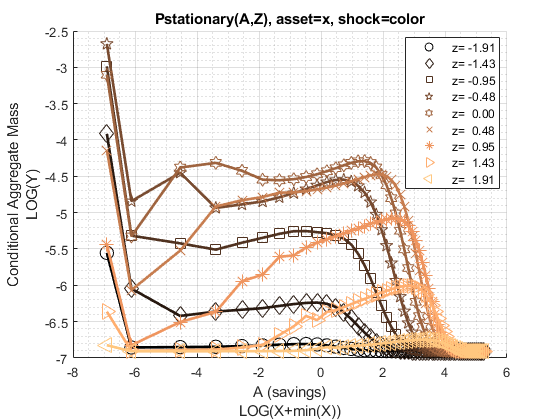

mp_support_graph('cl_st_graph_title') = {'Pstationary(A,Z), asset=x, shock=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
mp_support_graph('cl_st_xtitle') = {'A (savings)'};
mp_support_graph('st_rowvar_name') = 'z=';
mp_support_graph('it_legend_select') = 5; 
mp_support_graph('st_rounding') = '6.2f';
mp_support_graph('bl_graph_logy') = true;
mp_support_graph('cl_colors') = 'copper';
ff_graph_grid((tb_prob_az{1:end, 3:end})', eta_grid, agrid, mp_support_graph);% Consumption Choices

#### Asset Mass by Age

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [3,4,5,6,1,2];
% Value Function
tb_prob_aage = ff_summ_nd_array("P(A,Z))", Phi_true, true, ["sum"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings     sum_age_18    sum_age_19    sum_age_20    sum_age_21    sum_age_22    sum_age_23    sum_age_24    sum_age_25    sum_age_26    sum_age_27    sum_age_28    sum_age_29    sum_age_30    sum_age_31    sum_age_32    sum_age_33    sum_age_34    sum_age_35    sum_age_36    sum_age_37    sum_age_38    sum_age_39    sum_age_40    sum_age_41    sum_age_42    sum_age_43    sum_age_44    sum_age_45    sum_age_46   

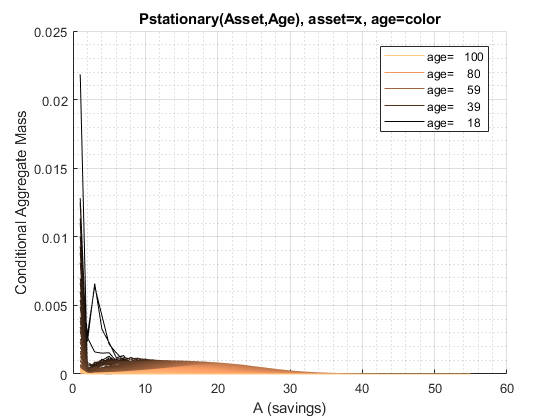

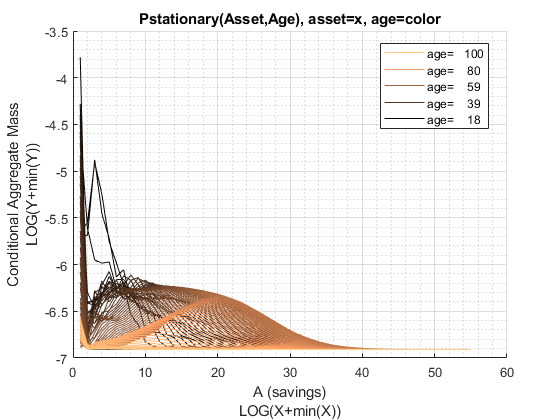

mp_support_graph('cl_st_graph_title') = {'Pstationary(Asset,Age), asset=x, age=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
mp_support_graph('cl_st_xtitle') = {'A (savings)'};
mp_support_graph('st_rowvar_name') = 'age=';
mp_support_graph('it_legend_select') = 5; 
mp_support_graph('st_rounding') = '6.0f';
mp_support_graph('bl_graph_logy') = true;
mp_support_graph('cl_colors') = 'copper';
ff_graph_grid((tb_prob_aage{1:end, 3:end})', age_grid, agrid, mp_support_graph);% Consumption Choices

## Probability Statistics A, C and V Conditional on Ages

Where are the mass at?

Phi_true = mp_dsvfi_results('Phi_true');
ap_ss = mp_dsvfi_results('ap_ss');
c_ss = mp_dsvfi_results('c_ss');
v_ss = mp_dsvfi_results('v_ss');
n_ss = mp_dsvfi_results('n_ss');
for it_ctr=1:size(ap_ss, 1)
    if (ismember(it_ctr, round(linspace(1, size(ap_ss, 1), 7))))
        display(['age =' num2str(age_grid(it_ctr))]);
        % construct input data
        Phi_true_age = Phi_true(it_ctr, :, :, : ,: ,:);
        ap_ss_age = ap_ss(it_ctr, :, :, : ,: ,:);
        c_ss_age = c_ss(it_ctr, :, :, : ,: ,:);
        v_ss_age = v_ss(it_ctr, :, :, : ,: ,:);
        n_ss_age = n_ss(it_ctr, :, :, : ,: ,:);
        
        mp_cl_ar_xyz_of_s = containers.Map('KeyType','char', 'ValueType','any');
        mp_cl_ar_xyz_of_s('ap_ss') = {ap_ss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('c_ss') = {c_ss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('v_ss') = {v_ss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('n_ss') = {n_ss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('ar_st_y_name') = ["ap_ss", "c_ss", "v_ss", "n_ss"];
        
        % controls
        mp_support = containers.Map('KeyType','char', 'ValueType','any');
        mp_support('ar_fl_percentiles') = [0.01 10 25 50 75 90 99.99];
        mp_support('bl_display_final') = true;
        mp_support('bl_display_detail') = false;    
        mp_support('bl_display_drvm2outcomes') = false;  
        mp_support('bl_display_drvstats') = false;
        mp_support('bl_display_drvm2covcor') = false;
    
        % Call Function     
        mp_cl_mt_xyz_of_s = ff_simu_stats(Phi_true_age(:)/sum(Phi_true_age,'all'), mp_cl_ar_xyz_of_s, mp_support);
    end
end

age =18


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss         c_ss         v_ss         n_ss   
    _____________________    _________    __________    _________    _________

      {'mean'        }        0.063555       0.65935       -33.39       1.9854
      {'sd'          }         0.12976       0.36549       27.837       1.0848
      {'coefofvar'   }          2.0417       0.55432     -0.83369      0.54639
      {'min'         }               0      0.089911      -285.06            1
      {'max'         }             190        11.049       25.213            6
      {'pYis0'       }          0.1081             0            0            0
      {'pYls0'       }               0             0      0.94197            0
      {'pYgr0'       }          0.8919             1     0.058034            1
      {'

age =32


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss         c_ss          v_ss         n_ss  
    _____________________    _________    __________    __________    ________

      {'mean'        }          1.1737        1.0198       -22.528      3.1931
      {'sd'          }          2.3027        0.5797        23.077      1.6311
      {'coefofvar'   }           1.962       0.56845       -1.0243     0.51083
      {'min'         }               0       0.12418       -196.11           1
      {'max'         }             190        13.436        23.362           6
      {'pYis0'       }         0.32246             0             0           0
      {'pYls0'       }               0             0        0.8565           0
      {'pYgr0'       }         0.67754             1        0.1435           1
      {'

age =45


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss          c_ss          v_ss         n_ss   
    _____________________    __________    __________    __________    _________

      {'mean'        }           4.1359        1.1251       -16.494       2.6143
      {'sd'          }           5.6341       0.69344        19.717       1.5259
      {'coefofvar'   }           1.3623       0.61633       -1.1954      0.58367
      {'min'         }                0       0.14084       -155.28            1
      {'max'         }              190        15.028        20.086            6
      {'pYis0'       }         0.065759             0             0            0
      {'pYls0'       }                0             0       0.78506            0
      {'pYgr0'       }          0.93424             1       0.21494  

age =59


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss          c_ss          v_ss         n_ss   
    _____________________    __________    __________    __________    _________

      {'mean'        }           9.3298         1.098       -13.346       1.7239
      {'sd'          }           9.4365       0.72709        16.354      0.90777
      {'coefofvar'   }           1.0114       0.66219       -1.2254      0.52659
      {'min'         }                0       0.13792       -118.34            1
      {'max'         }              190        16.001        15.244            6
      {'pYis0'       }        0.0029257             0             0            0
      {'pYls0'       }                0             0        0.7711            0
      {'pYgr0'       }          0.99707             1        0.2289  

age =73


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss          v_ss          n_ss   
    _____________________    _________    _________    __________    __________

      {'mean'        }          8.5031      0.98016        -11.76        1.5002
      {'sd'          }          8.3099      0.67879        12.118       0.54035
      {'coefofvar'   }         0.97729      0.69253       -1.0304       0.36017
      {'min'         }               0      0.21429       -79.363             1
      {'max'         }          180.87       18.922        9.8752             6
      {'pYis0'       }        0.011431            0             0             0
      {'pYls0'       }               0            0       0.82454             0
      {'pYgr0'       }         0.98857            1       0.17546             

age =86


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss         c_ss         v_ss         n_ss   
    _____________________    __________    ________    __________    _________

      {'mean'        }            2.451     0.72931       -10.978       1.4839
      {'sd'          }           3.0546     0.51898        7.8913      0.51163
      {'coefofvar'   }           1.2463      0.7116      -0.71881      0.34478
      {'min'         }                0     0.21429       -45.275            1
      {'max'         }           169.66      32.075        5.2577            6
      {'pYis0'       }         0.098393           0             0            0
      {'pYls0'       }                0           0        0.9447            0
      {'pYgr0'       }          0.90161           1      0.055301            1
      {'

age =100


xxx tb_outcomes: all stats xxx
    OriginalVariableNames    ap_ss      c_ss          v_ss          n_ss   
    _____________________    _____    _________    __________    __________

      {'mean'        }          0       0.24393       -4.0816        1.4797
      {'sd'          }          0      0.066296        1.0975       0.50567
      {'coefofvar'   }        NaN       0.27178      -0.26888       0.34173
      {'min'         }          0       0.21429        -10.31             1
      {'max'         }          0        195.96        0.9949             6
      {'pYis0'       }          1             0             0             0
      {'pYls0'       }          0             0       0.99985             0
      {'pYgr0'       }          0             1    0.00014645             1
      {'pYisMINY'    }          1     